# Filtros discretos FIR

Autor: M en TA. Jheison Duvier Diaz Ortega

## Resumen

*En esta actividad de  aprendizaje se realiza la implementación de las diferentes configuraciones de los filtros digitales de Respuesta Finita al Impulso, esta actividad es un complemento de la teoría sobre los FIR vista en clase. La propuesta consiste en elegir una canción a la cual se le debe filtrar con filtros FIR Pasa altas, pasa bajas, pasa banda y banda eliminada.*

## Objetivos de Aprendizaje

-Comprender las diferencias entre las distintas configuraciones de los FIR.

-Comprender y aplicar los conceptos básicos en el diseño de filtros digitales.

-Afianzar los conocimientos y habilidades de Matlab y Simulink como una herramienta valiosa en la ingeniería.

## Antes de empezar 

Esta actividad está pensada para probar la teoría sobre los filtros FIR, que en su mayoría no es muy sencillo de entender si no se pone en práctica, los alumnos deben tener conocimientos básicos sobre matlab y simulink, y deben ser alumnos de carreras como ingeniería electrónica, mecatrónica, ingeniería de sonido entre otras a fin.

 Se propone usar matlab por la facilidad para la implementación, y las múltiples funciones que permiten el estudio y aprendizaje de los diferentes filtros digitales.

## Sección 1: Conceptos 

 Se utilizarán las funciones del toobox de procesamiento de señales digitales para diseñar los 4 tipos de filtros. Utilizarán la función FIR1 para generar el vector de ganancias que luego será el mismo que se agregará en el bloque de Simulink para posteriormente introducir la canción y realizar el filtrado.

## Sección 2: Ejercicio 1

Obtenga los vectores de cada filtro de la siguiente manera, el ejemplo contiene los ejercicios de los filtros pasa altas y pasa bajas, usted debe completar el ejercicio para el pasa bandas y banda eliminada (se debe consultar la documentación de la fución Fir1). Los criterios para el diseño del filtro pueden ser modificados egún sus propios criterios y necesidades de filtrado.

% Criterios para el diseño del FIR

fc = 1000; % Frecuencia de corte
fs = 48000; % Frecuencia de muestreo
n = 200; % Orden del filtro

% Diseño del filtro

b1 = fir1(n,fc/(fs/2),'LOW'); %Filtro pasa bajas
b2 = fir1(n,fc/(fs/2),'HIGH'); %Filtro para altas

## Sección 3: Ejercicio 2

Utiliza los vectores b1, b2 y los otros dos que deben crearse (para los filtros pasa bandas y banda eliminada) para las demás configuraciones en los bloques de Simulink como en la siguiente imagen. Consiga un archivo de audio de su preferencia y utilícelo para probar las 4 configuraciones planteadas. Es importante que su archivo de Simulink esté guardado en el mismo folder donde guardó el script donde calculó los vectores b1, b2, etc.

Al ejecutar las dos siguientes líneas de código, se abrirá el ejemplo de un modelo de simulink que puede ser utilizado para la actividad.

mdl = "Practica";
open_system(mdl)

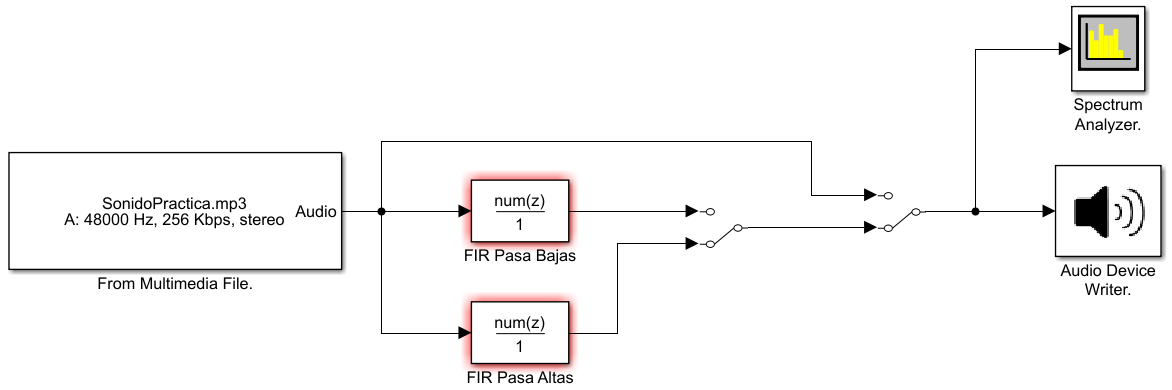

## Recursos Adicionales

Puede consultar como material de apoyo en la actividdad la serie de videos sobre filtros FIR del profesor** José Javier López Monfort **de la *Universidad Politécnica de Valencia* en el siguiente enlace [https://www.youtube.com/watch?v=ENIFBriOrHI&t=27s](https://www.youtube.com/watch?v=ENIFBriOrHI&t=27s)